# NWB Tutorial- Reading NWB data in MATLAB

## Introduction

In this tutorial, we will read single neuron spiking data that is in the NWB standard format and do a basic visualization of the data.

## Download the data

First, let's download an NWB data file from the [DANDI neurophysiology data archive](https://dandiarchive.org/).

An NWB file represents a single session of an experiment. It contains all the data of that session and the metadata required to understand the data.

We will use data from one session of an experiment by [Chandravadia et al. (2020)](https://www.nature.com/articles/s41597-020-0415-9), where the authors recorded single neuron activity from the medial temporal lobes of human subjects while they performed a recognition memory task.

- Go to the DANDI page for this dataset: [https://dandiarchive.org/dandiset/000004/draft](https://dandiarchive.org/dandiset/000004/draft)

- Toward the top middle of the page, click the "View Data" button.

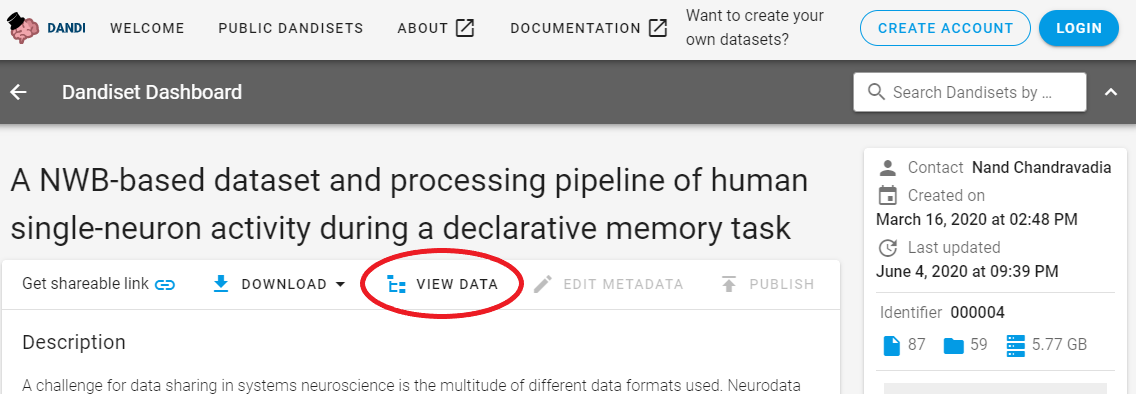

          3. Click on the folder "sub-P11MHM" (click the folder name, not the checkbox).

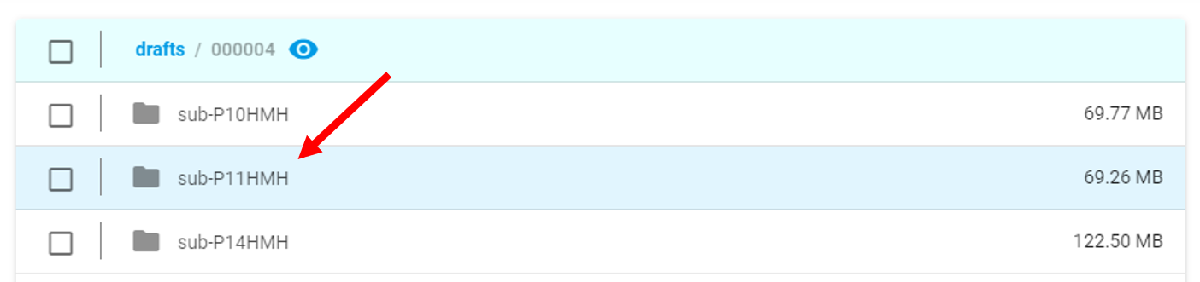

          4. Then click on the download symbol to the right of the filename "sub-P11HMH_ses-20061101_ecephys+image.nwb" to download the data file (69 MB) to your computer.

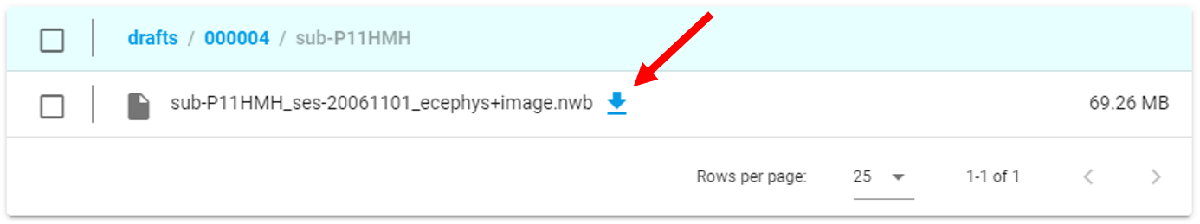

## Installing matnwb

Use the code below within the comment brackets to install MatNWB from source. MatNWB works by automatically creating API classes based on the schema. Use `generateCore()` to generate these classes.

%{
!git clone https://github.com/NeurodataWithoutBorders/matnwb.git

nwb =   NwbFile with properties:

                                nwb_version: '2.1.0'
                                acquisition: [2×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                           file_create_date: [1×1 types.untyped.DataStub]
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: 'learning: 80, recognition: 81'
                            general_devices: [1×1 types.untyped.Set]
             general_experiment_description: 'The data contained within this file describes a new/old recogntion task performed in patients with intractable epilepsy implanted with depth electrodes and Behnke-Fried microwires in the human Medical Temporal Lobe (MTL).'
                       general_experimenter: []
                general_extracellular_ephys: [9×1 types.untyped.Set]
     general_extracellular_ephys_ele

cd matnwb
addpath(genpath(pwd));
generateCore();
%}

After downloading an NWB file representing the data from a single session, read it with `nwbRead`. You will find that the print out for this shows a summary of the data within.

nwb = nwbRead('/Volumes/easystore5T/data/Rutishauser/dandi_data/sub-P11HMH_ses-20061101_ecephys+image.nwb')

ans =   Set with properties:

    StimulusPresentation: [types.core.OpticalSeries]


You can also use `util.nwbTree` to actively explore the NWB file.

util.nwbTree(nwb);

ans =   OpticalSeries with properties:

                        distance: 0.7000
                   field_of_view: [1×1 types.untyped.DataStub]
                     orientation: 'lower left'
                       dimension: [1×1 types.untyped.DataStub]
                   external_file: []
    external_file_starting_frame: []
                          format: 'raw'
              starting_time_unit: 'seconds'
             timestamps_interval: 1
                 timestamps_unit: 'seconds'
                        comments: 'no comments'
                         control: []
             control_description: []
                            data: [1×1 types.untyped.DataStub]
                 data_conversion: 1
                 data_resolution: -1
                       data_unit: 'meters'
                     description: 'no description'
                   starting_time: []
              starting_time_rate: []
 

### Stimulus

Now lets take a look at the visual stimuli presented to the subject. They will be in `nwb.stimulus_presentation`

nwb.stimulus_presentation

ans =   DataStub with properties:

    filename: '/Volumes/easystore5T/data/Rutishauser/dandi_data/sub-P11HMH_ses-20061101_ecephys+image.nwb'
        path: '/stimulus/presentation/StimulusPresentation/data'
        dims: [3 300 400 200]


This results shows us that `nwb.stimulus_presentation` is a `Set` object that contains a single data object called `StimulusPresentation`, which is an `OpticalSeries` neurodata type. Use the `get` method to return this `OpticalSeries`.

nwb.stimulus_presentation.get('StimulusPresentation')

`OpticalSeries` is a neurodata type that stores information about visual stimuli presented to subjects. This print out shows all of the attributes in the `OpticalSeries` object named `StimulusPresentation`. The images are stored in `StimulusPresentation.data`

nwb.stimulus_presentation.get('StimulusPresentation').data

When calling a data object directly, the data is not read but instead a `DataStub` is returned. This is because data is read "lazily" in MatNWB. Instead of reading the entire dataset into memory, this provides a "window" into the data stored on disk that allows you to read only a section of the data. In this case, the last dimension indexes over images. To pull out only a single image index, use the `load` method like this:

% get image and display it
image_index = 31;
img = nwb.stimulus_presentation.get('StimulusPresentation'). ...
    data.load([1, 1, 1, image_index], [3, 300, 400, image_index]);

This pulls out 1:3 of the first dimension, 1:300 of the second dimension, 1:400 of the third dimension, and image_index of the last dimension.

A bit of manipulation allows us to display the image using MATLAB's `imshow`.

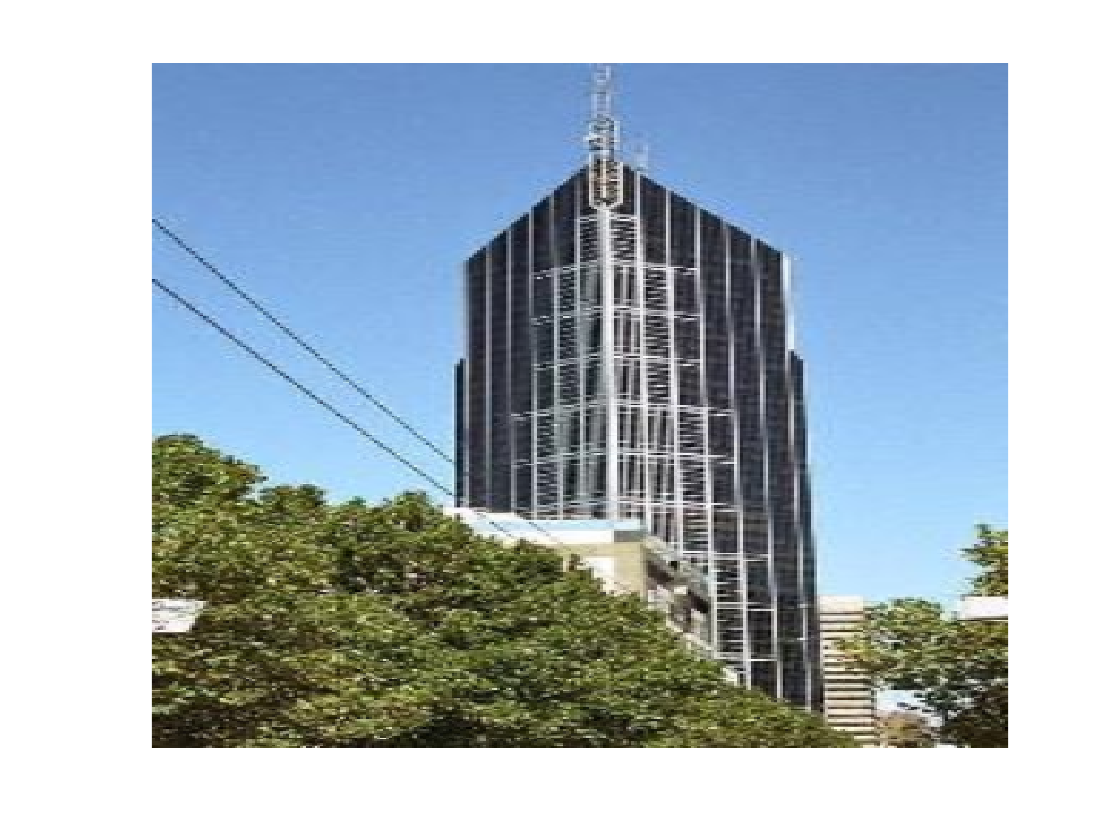

img = permute(img,[3, 2, 1]);  % fix orientation
img = img(:, :, end:-1:1);  % fix the fact that img is BGR

figure();
imshow(img);
daspect([3, 5, 5]);

To read an entire dataset, use the `DataStub.load` method without any input arguments. We will use this apprach to read all of the image display timestamps into memory.

times = nwb.stimulus_presentation.get('StimulusPresentation').timestamps.load;

## Quick PSTH and raster

Here I'll demonstrate a quick script that pulls out spike times of a particular unit and aligns them to the image display times, then displays the results.

%% Align spikes by stimulus presentations

unit_ind =9;
before =1;
after =3;

Spikes are stored in an NWB construct called an indexed column, which allows us to efficiently store matrices where each row has a different number of elements. `util.read_indexed_column` provides a convenient method for reading this data out.

unit_spikes = util.read_indexed_column( ...
    nwb.units.spike_times_index, ...
    nwb.units.spike_times, ...
    unit_ind);

Spike times from this unit are aligned to each stimulus time and compiled in a cell array

results = {};
for itime = 1:length(times)
    time = times(itime);
    spikes = unit_spikes - time;
    spikes = spikes(spikes > -before);
    spikes = spikes(spikes < after);
    results{itime} = spikes;
end

And finally here is a (slightly sloppy) peri-stimulus time histogram

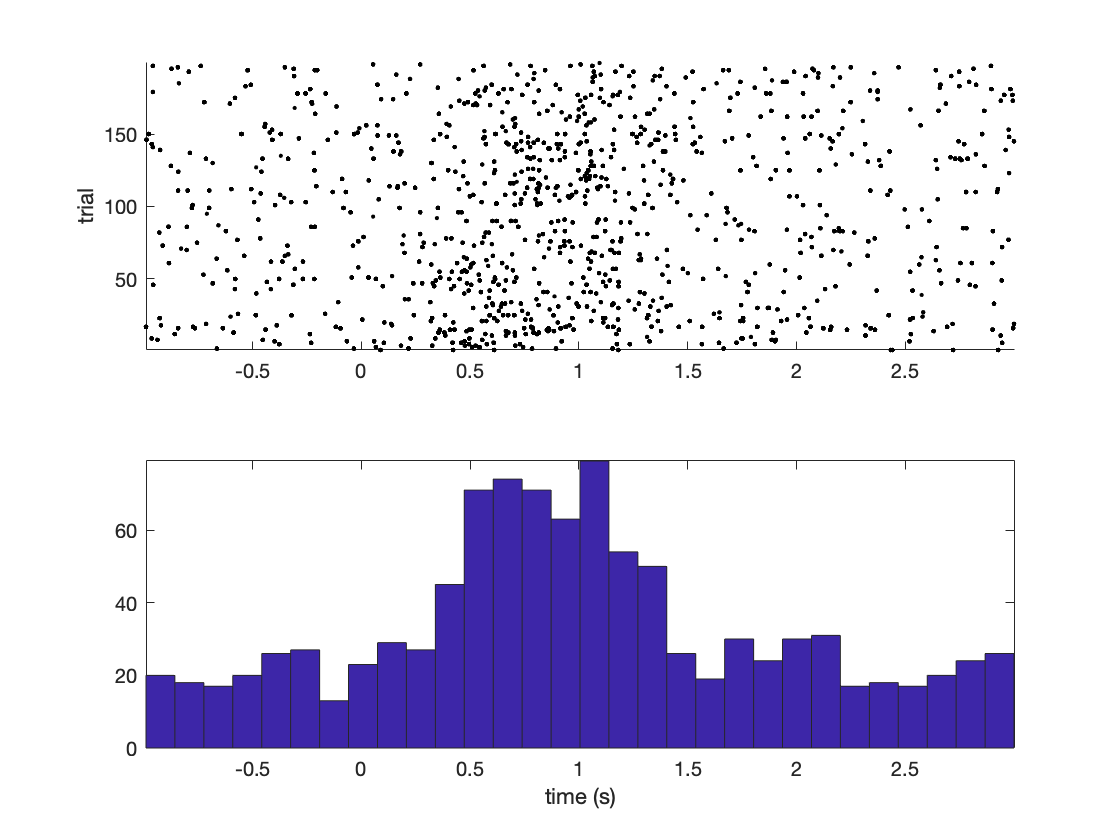

%% Plot results
figure();
subplot(2, 1, 1);
hold on
for i = 1:length(results)
    
    spikes = results{i};
    yy = ones(length(spikes)) * i;
    
    plot(spikes, yy, 'k.');

end
hold off
ylabel('trial');
axis('tight')

subplot(2, 1, 2);
all_spikes = cat(1, results{:});
hist(all_spikes, 30);
xlabel('time (s)');
axis('tight')

## Conclusion

This is an example of how to get started with understanding and analyzing public NWB datasets. This particular dataset was published with an extensive open analysis conducted in both MATLAB and Python, which you can find [here](https://github.com/rutishauserlab/recogmem-release-NWB). For more datasets, or to publish your own NWB data for free, check out the DANDI archive [here](http://dandiarchive.org/). Also, make sure to check out the DANDI breakout session later in this event.